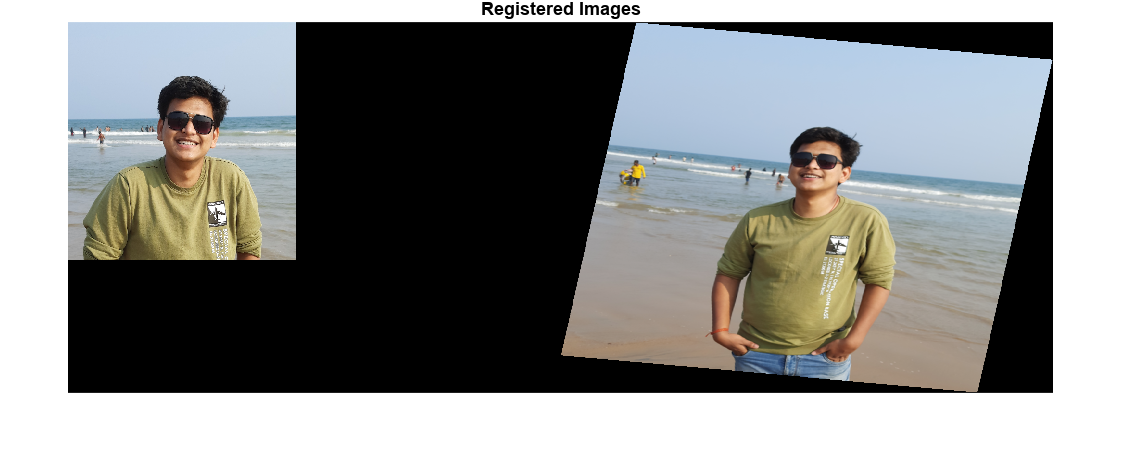

% Load the two images to be registered
I1 = imread('close.png');
I2 = imread('far.png');

% Detect SURF features in both images
points1 = detectSURFFeatures(rgb2gray(I1));
points2 = detectSURFFeatures(rgb2gray(I2));

% Extract SURF feature descriptors
[f1, vpts1] = extractFeatures(rgb2gray(I1), points1);
[f2, vpts2] = extractFeatures(rgb2gray(I2), points2);

% Match the features between the two images
indexPairs = matchFeatures(f1, f2);

% Retrieve the locations of the corresponding points in both images
matchedPoints1 = vpts1(indexPairs(:, 1));
matchedPoints2 = vpts2(indexPairs(:, 2));

% Estimate the geometric transformation between the two images
[tform, inlierPoints2, inlierPoints1] = estimateGeometricTransform(matchedPoints2, matchedPoints1, 'affine');

% Apply the transformation to one of the images
registered = imwarp(I2, tform);

% Show the registered image
imshowpair(I1, registered, 'montage');
title('Registered Images');